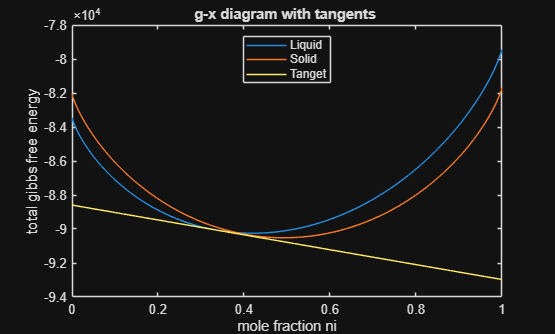

%experiment no  determination of chemical potential for cu ni alloy in
%liquid state
% %name of programmer=Sahil Patra
clc
clear all
close all
R=8.314;%universal gas constant
T=1500;%temperature of solution  in k 
X_NI=[eps:0.001:1];%mole frsction of ni
x_cu=1-X_NI;%mole fraction of cu

n=length(X_NI);
del_s(1)=0;
del_s(n)=0;
for i=2:n-1
    del_s(i)=X_NI(i).*log(X_NI(i))+x_cu(i)*log(x_cu(i));
end
del_s=-del_s*R;
g_ts=-T*del_s;

%gibbs free energy cslculstion for pure copper
if T>=298.15 && T<=1358
    Go_Cu_l=5194.277 + 120.973331 *T - (24.112392 *T *log(T)) - 2.65684*(10^-3) *(T^2) + 0.129223*(10^-6)* (T^3) + 52478 *(T^-1) - 584.89*(10^-23) *(T^7) ;

end
if T>1358 && T<3200
    Go_Cu_l=-46.545 + 173.881484*(T) - 31.38 *(T)* log(T);
end



%gibbs free energy cslculstion for pure Ni
if T>=298.15 && T<=1728
    Go_ni_l=11235.527 + 108.457 *T - 22.096 *T* log(T) - 4.8407*(10^-3)* (T^2) - 382.318*(10^-23)* (T^7);
end
if T>1728 && T<3000
    Go_ni_l=-9549.817 + 268.597977 *T - 43.1 *T *log(T) ;
end
%calculation of total gibbs free energy 
G_l=x_cu*Go_Cu_l+X_NI*Go_ni_l+g_ts;
plot(X_NI,G_l);
m=min(G_l);
hold on
xlabel("mole fraction ni");
ylabel("total gibbs free energy");
title("g-x diagram with tangents ");
%plot(X_NI,del_s)

%---------------------------------------------------for solid phase ____________________




%experiment no  determination of chemical potential for cu ni alloy in
%solid state
%calculation of entropty
%gibbs free energy cslculstion for pure copper in solid state
if T>= 298.15 && T<= 1357.77
    Go_Cu_s= -7770.458 + 130.485235*T - 24.112392*T*log(T) - 2.65684*(10^(-3))*T^2 + 0.129223*(10^(6))*(T^(3)) + 52478*(T^(-1));
end
if T>1358 && T<3200
    Go_Cu_s= -13542.026 + 183.803828*T - 31.38*T*log(T) + 364.167*(10^(27))*(T^(-9));
end

%Gibbs Free Energy Calculation for Pure Nickel in Liquid State (Data Source: SGTE,1991)
if T>= 298.15 && T<= 1728
    go_Ni_S= -5179.159 + 117.854*T - 22.096*T*log(T) - 4.8407*(10^(-3))*(T^2);
end
if T>1728 && T<3000
    go_Ni_S= -27840.620 + 279.134977*T - 43.1*T*log(T) + 1127.54*(10^(28))*(T^(-9)); 
end
%calculation of total gibbs free energy 
G_s=x_cu*Go_Cu_s+X_NI*go_Ni_S+g_ts;
plot(X_NI,G_s);

xlabel("mole fraction ni");
ylabel("total gibbs free energy");
title("g-x diagram with tangents ");
%plot(X_NI,del_s)
hold off
%common tangent
%\\----------------------
idx = find(abs(G_l - G_s) == min(abs(G_l - G_s)));
cross_index=idx;
start_index_L= cross_index-150;
end_index_L= cross_index;
start_index_S= cross_index;
end_index_S= cross_index+150;
dy=diff(G_l);
dx=diff(X_NI);
m=dy./dx;
for i =start_index_L:end_index_L
    x1=X_NI(i);
    y1=G_l(i);
    y_line=y1+m(i)*(X_NI-x1);
    
    a=m(i);
    b=-1;
    c=y1-m(i)*x1;
    k=1;
    for j =start_index_S:end_index_S
        xx1=X_NI(j);
        yy1=G_s(j);
        num=abs(a*xx1+b*yy1+c);
        din=sqrt(a^2+b^2);
        dis(k)=num/din;
        k=k+1;
    end
    [val,in]=min(dis);
    if val  <0.01
        eq_ni_l=X_NI(i);
        eq_ni_s=X_NI(start_index_S+in);
        break
    end
end
hold on
plot(X_NI,y_line)
legend('Liquid','Solid','Tanget',Location='north')

fprintf('composition of liquid phase in equilibrium with solid iin 1500 k is %f\n',eq_ni_l)

composition of liquid phase in equilibrium with solid iin 1500 k is 0.337000


fprintf("composition of solid phase in equilibrium with liquid in 1500 k is %f\n ",eq_ni_s)

composition of solid phase in equilibrium with liquid in 1500 k is 0.407000
 